## **Universal Biquad filter**

clear;clc;
fp = 1e3;
Qp = 30;
wp = 2*pi*fp;
a2 = 1;
a0 = a2*wp^2;
a1 = a2*wp;
fs = linspace(800, 1200, 320);
ws = 2*pi*fs;

## **Values of Resistors and Capacitors**

C1 = 100e-9;  %Assumed
C2 = C1;
R1 = 1/(wp*C1);
R2 = R1*a2;
R3 = R1*Qp;
R7 = R1;
R4 = R1;
R6 = R4;
R5 = R1;
R8 = R5;
X=['R1 = ',num2str(R1),' R2 = ',num2str(R2),'  R3 = ' ,num2str(R3),' R4 = ' ,num2str(R4),' R5 = ' ,num2str(R5),' R6 = ' ,num2str(R6),' C1 = ' ,num2str(C1),' C2 = ',num2str(C2)];
disp(X);

R1 = 1591.5494 R2 = 1591.5494  R3 = 47746.4829 R4 = 1591.5494 R5 = 1591.5494 R6 = 1591.5494 C1 = 1e-07 C2 = 1e-07


## **High Pass Filter Transfer Function from design equations of Universal Biquad filter**

num1 = [a2 0 0];
den1 = [1 wp/Qp wp^2];
H1 = tf(num1,den1);
[mag1, phase1] = bode(H1,ws);
% Plot bode diagram
db1 = 20*log10(mag1);
db1 = db1(:,:); %to match the matrix dimensions with fs;
phase1 = phase1(:,:); %to match the matrix dimensions with fs;

% Generate the magnitude plot and phase
figure('NumberTitle', 'off', 'Name', 'HighPass Filter Magnitude and Phase Response');
title('HighPass Filter Response')
subplot(3,1,1);
semilogx(fs,db1,'linewidth',2);
grid on;
xlabel('Frequency f/Hz');
ylabel('Magnitude H/dB');
subplot(3,1,2);
semilogx(fs,phase1,'linewidth',2);
grid on;
xlabel('Frequency f/Hz');
ylabel('Phase phi/deg');

subplot(3,1,3);
[z1,p1,~] = tf2zp(num1,den1)

z1 =      0
     0


p1 = 	1.0e+03 *

  -0.1047 + 6.2823i
  -0.1047 - 6.2823i


[z1,p1,~] = zplane(z1,p1)

z1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 7
    MarkerFaceColor: 'none'
              XData: [0 0]
              YData: [1.0000e-50 1.0000e-50]
              ZData: [1×0 double]

  Show all properties


p1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'x'
         MarkerSize: 8
    MarkerFaceColor: 'none'
              XData: [-104.7198 -104.7198]
              YData: [6.2823e+03 -6.2823e+03]
              ZData: [1×0 double]

  Show all properties


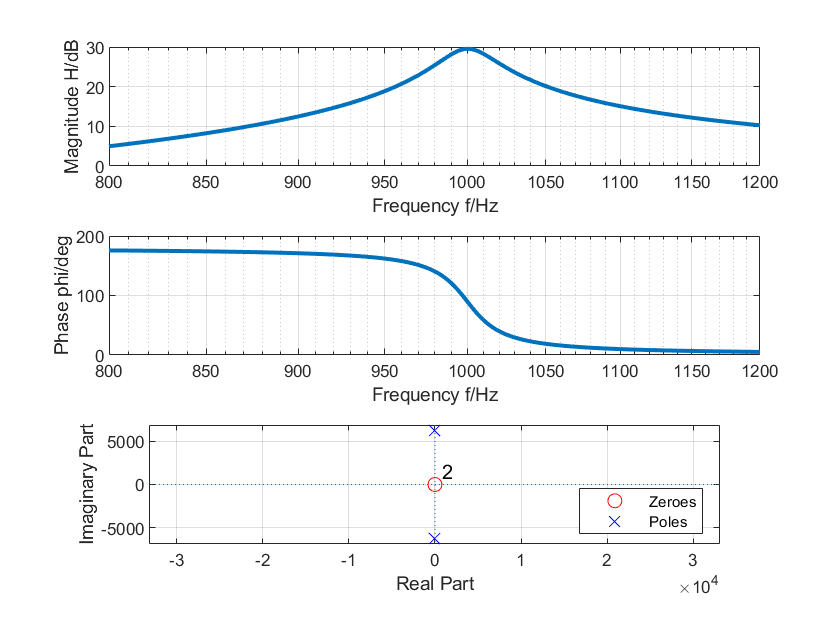

hold off;
set(findobj (z1, 'Type' , 'line' ), 'Color' , 'r' );
set(findobj (p1, 'Type' , 'line' ), 'Color' , 'b' );
legend('Zeroes','Poles','Location','southeast'), grid;

## **Low Pass Filter Transfer Function from design equations of Universal Biquad filter**

num2 = [0 0 a0];
den2 = [1 wp/Qp wp^2];
H2 = tf(num2,den2);
% Plot bode diagram
[mag2, phase2] = bode(H2,ws);
db2 = 20*log10(mag2);
db2 = db2(:,:);
phase2 = phase2(:,:);

% Generate the magnitude plot and phase
figure('NumberTitle', 'off', 'Name', 'Low Pass Filter Magnitude and Phase Response');
subplot(3,1,1);
semilogx(fs,db2,'linewidth',2);
grid on;
xlabel('Frequency f/Hz');
ylabel('Magnitude H/dB');
subplot(3,1,2);
semilogx(fs,phase2,'linewidth',2);
grid on;
xlabel('Frequency f/Hz');
ylabel('Phase phi/deg');

subplot(3,1,3);
[z2,p2,~] = tf2zp(num2,den2)


z2 =

  0×1 empty double column vector



p2 = 	1.0e+03 *

  -0.1047 + 6.2823i
  -0.1047 - 6.2823i


[z2,p2,~] = zplane(z2,p2)

z2 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 7
    MarkerFaceColor: 'none'
              XData: NaN
              YData: 0
              ZData: [1×0 double]

  Show all properties


p2 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'x'
         MarkerSize: 8
    MarkerFaceColor: 'none'
              XData: [-104.7198 -104.7198]
              YData: [6.2823e+03 -6.2823e+03]
              ZData: [1×0 double]

  Show all properties


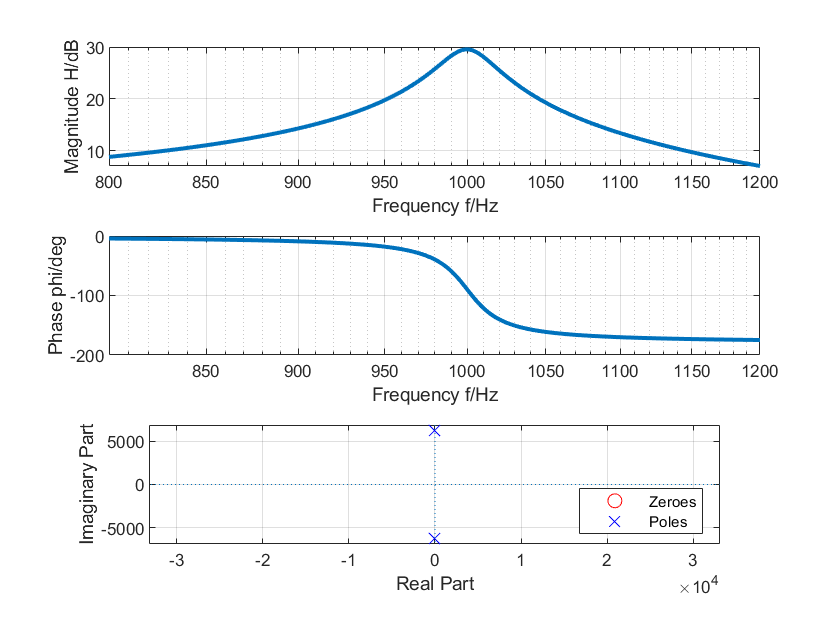

hold off;
set(findobj (z2, 'Type' , 'line' ), 'Color' , 'r' );
set(findobj (p2, 'Type' , 'line' ), 'Color' , 'b' );
legend('Zeroes','Poles','Location','southeast'), grid;

## **Band-Pass Filter Transfer Function from design equations of  Universal Biquad filter**

num3 = [0 a1 0];
den3 = [1 wp/Qp wp^2];
H3 = tf(num3,den3);
% Plot bode diagram
[mag3, phase3] = bode(H3,ws);
db3 = 20*log10(mag3);
db3 = db3(:,:);
phase3 = phase3(:,:);

% Generate the magnitude plot and phase
figure('NumberTitle', 'off', 'Name', 'LowPass Filter Magnitude and Phase Response');
subplot(3,1,1);
semilogx(fs,db3,'linewidth',2);
grid on;
xlabel('Frequency f/Hz');
ylabel('Magnitude H/dB');
subplot(3,1,2);
semilogx(fs,phase3,'linewidth',2);
grid on;
xlabel('Frequency f/Hz');
ylabel('Phase phi/deg');

subplot(3,1,3);
[z3,p3,~] = tf2zp(num3,den3)

z3 = 0

p3 = 	1.0e+03 *

  -0.1047 + 6.2823i
  -0.1047 - 6.2823i


[z3,p3,~] = zplane(z3,p3)

z3 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 7
    MarkerFaceColor: 'none'
              XData: 0
              YData: 1.0000e-50
              ZData: [1×0 double]

  Show all properties


p3 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'x'
         MarkerSize: 8
    MarkerFaceColor: 'none'
              XData: [-104.7198 -104.7198]
              YData: [6.2823e+03 -6.2823e+03]
              ZData: [1×0 double]

  Show all properties


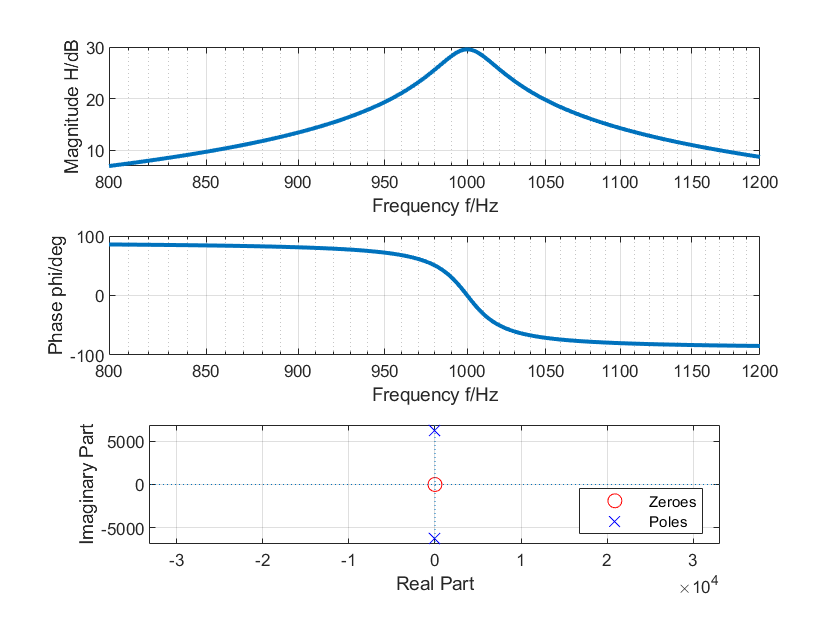

hold off;
set(findobj (z3, 'Type' , 'line' ), 'Color' , 'r' );
set(findobj (p3, 'Type' , 'line' ), 'Color' , 'b' );
legend('Zeroes','Poles','Location','southeast'), grid;

## **Band-Notch Filter Transfer Function from design equations of  Universal Biquad filter**

num4 = [ a2 0 a0 ];
den4 = [1 wp/Qp wp^2];
H4 = tf(num4,den4);
% Plot bode diagram
[mag4, phase4] = bode(H4,ws);
db4 = 20*log10(mag4);
db4 = db4(:,:);
phase4 = phase4(:,:);

% Generate the magnitude plot and phase
figure('NumberTitle', 'off', 'Name', 'Band notch Filter Magnitude and Phase Response');
subplot(3,1,1);
semilogx(fs,db4,'linewidth',2);
grid on;
xlabel('Frequency f/Hz');
ylabel('Magnitude H/dB');
subplot(3,1,2);
semilogx(fs,phase4,'linewidth',2);
grid on;
xlabel('Frequency f/Hz');
ylabel('Phase phi/deg');

subplot(3,1,3);
[z4,p4,~] = tf2zp(num4,den4)

z4 = 	1.0e+03 *

   0.0000 + 6.2832i
   0.0000 - 6.2832i


p4 = 	1.0e+03 *

  -0.1047 + 6.2823i
  -0.1047 - 6.2823i


[z4,p4,~] = zplane(z4,p4)

z4 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 7
    MarkerFaceColor: 'none'
              XData: [0 0]
              YData: [6.2832e+03 -6.2832e+03]
              ZData: [1×0 double]

  Show all properties


p4 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'x'
         MarkerSize: 8
    MarkerFaceColor: 'none'
              XData: [-104.7198 -104.7198]
              YData: [6.2823e+03 -6.2823e+03]
              ZData: [1×0 double]

  Show all properties


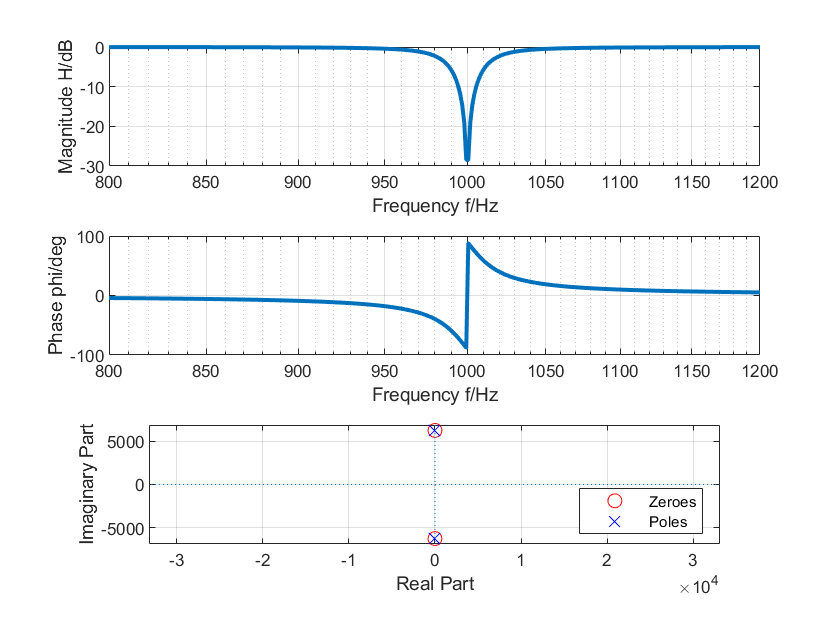

hold off;
set(findobj (z4, 'Type' , 'line' ), 'Color' , 'r' );
set(findobj (p4, 'Type' , 'line' ), 'Color' , 'b' );
legend('Zeroes','Poles','Location','southeast'), grid;